# Lab 4

## Q1

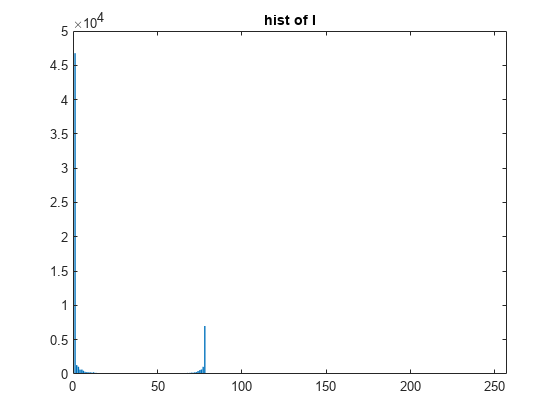

clc,clear;
%1. Get PCB.gif using UI. keep for late use
%[f_name,f_path]=uigetfile();
%filepath=[f_path f_name];
%I=imread(filepath);
I=imread("PCB.gif");
Hist_of_I=figure();
Hist_I=imhist(I(:));
bar(Hist_I);
title("hist of I");
saveas(Hist_of_I,"Hist_of_I",'jpg');

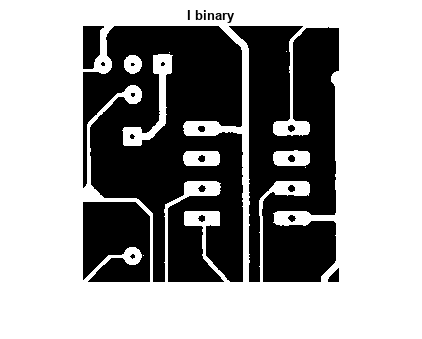

%we found that the major pixels are around 0 and 80. we will take 40.
thresh=graythresh(Hist_I)*64;
%the value is close. we got 31.8745

%2. binary convert
I_bin=I>thresh;
I_bin_fig=figure();
imshow(I_bin);
title("I binary")

saveas(I_bin_fig,"I_bin_fig",'jpg');
%Inverse image
not_I_bin=not(I_bin);
imshow(not_I_bin);
title("inverse of I");
%4.
%creating one mask for the background
blackmask=zeros(size(I));
blackmask(1:end,1)=1;
blackmask(1:end,end)=1;
blackmask(1,1:end)=1;
blackmask(end,1:end)=1;
imshow(blackmask);
title("The mask");

%making one label for the background
not_I_bin2=blackmask|not_I_bin;

%label the masked image
Label_not_I_bin=bwlabel(not_I_bin2);

% %debug get the number of labels
% max(max(Label_not_I_bin));

%binary convert for the holes
Label_not_I_bin=Label_not_I_bin>1;
imshow(uint8(Label_not_I_bin),[]);
title("holes");



output=Label_not_I_bin|I_bin;
imshow(output);
title("Output");

%5.

%getting the stast of the objects.
stats = regionprops('table',Label_not_I_bin,'Centroid',...
    'MajorAxisLength','MinorAxisLength');

%centers- all the centers of the object
centers = stats.Centroid;
%getting the mean of major and the minor axis diameters.
diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
radii = diameters/2;
% %another way to calculate:
% radii=stats.MajorAxisLength/2;
hold on
viscircles(centers,radii);
hold off

## Q2

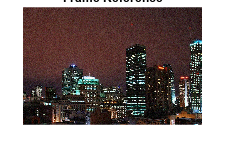

%1st part
vidobj = VideoReader('Weather_Cam.avi');
numFrames = get(vidobj, 'NumberOfFrames');

%getting the best correlation
%normxcorr2(
%fit the result
%tform=fitgeotrans
%imwarp
Frame_Avrg=im2double(read(vidobj,1));
ref_frame=Frame_Avrg;
imshow(ref_frame);
title("Frame Reference");

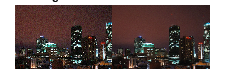

% (161, 198)  [0.44 0.25 0.26]
% (194, 216)  [0.27 0.26 0.29]

% ys=343;
% xs=217;
% %end cordinats
% deltay=358-ys;
% deltax=242-xs;
% rectM=[ys xs deltay deltax];
% %making the mask
% _mask=imcrop(I_text,rectS);

%mask=imcrop(ref_frame,rect);
N_avg=16;
for i=2:N_avg
 Frame=im2double(read(vidobj, i));

 %res=normxcorr2(ref_frame,Frame);

 Frame_Avrg= Frame_Avrg+Frame;
end
Frame_Avrg= Frame_Avrg/N_avg;
figure
montage({Frame,Frame_Avrg})
title('Average Frame after 16 interaction');



%2nd part
frame=rgb2gray(Frame_Avrg);
dx=-4; %pixels
dy=-4; %pixels
theta = -3;
tform = affine2d([ ...
 cosd(theta) sind(theta) 0;...
 -sind(theta) cosd(theta) 0; ...
 dx dy 1])

tform =   affine2d with properties:

                 T: [3×3 double]
    Dimensionality: 2


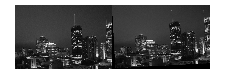

OutputView =affineOutputView(size(frame),tform,'BoundsStyle','sameAsInput');
Gframe = imwarp(frame,tform, 'FillValues',0,'OutputView',OutputView);
montage({frame,Gframe})